[x, Fs] = audioread('matlab.mp3')

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 44100

sound(x, Fs);
 
y = zeros(length(x), 1);
a = 0.5;
ts = 1/Fs;
n0 = 0.5/ts

n0 = 22050

for n = 1:length(x)
    if(n - n0 > 0)
        y(n) = x(n) + a*x(n-n0);
    else 
        y(n) = x(n);
    end
end
sound(y, Fs);

h = [1 zeros(1,n0-1) a]

h =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



y2 = conv(x, h)

y2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


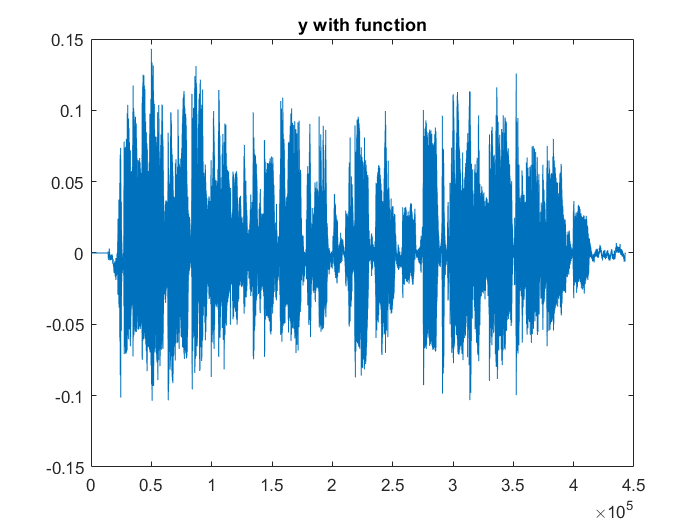

sound(y2, Fs)

plot(y)
title("y with function")

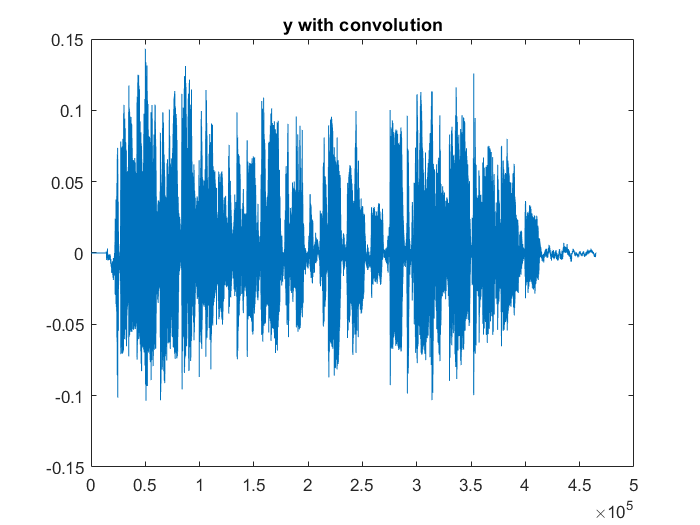

plot(y2)
title("y with convolution")


y3 = conv(flip(x), y)

y3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


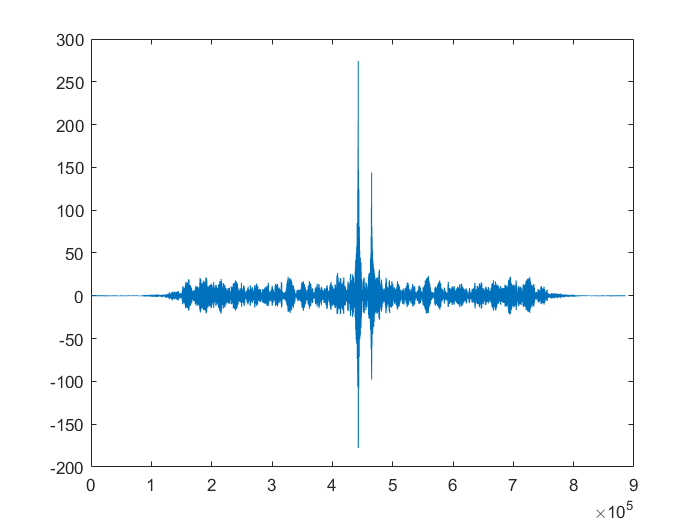

plot(y3)

y4 = y3;
y4 (y4 < 140) = 0;
[val, idx] = findpeaks(y4);
[x,y] = max(val);
[x1, y1] = min(val);
n0 =  idx(y1)-idx(y)

n0 = 22053